# 6DOF SIMULATION OF LUNAR LANDER

clear all; close all;
global m MOI dt t_go K

## INITIALIZE STATE

Initialize;

## SIMULATION

dt = 0.1;

i = 1;
t_go = 30;

state = initial_state; 

z = state(3);

acc_temp = guidance_moon_final(state,state_t);

state =          100         100       -1500         -25           0          80           0           0           0           0           0           0


lsqr이(가) 반복 2에서 해로 수렴했습니다(상대 잔차: 2.7e-13).


% acc = kron(acc_temp,ones(10,1));
acc = acc_temp;

dt = 0.1;
while i <= t_go/dt - 100
    % Update state
    save_state(i,:) = state;

    % Translate Acceleration command to Euler angle
    angle_cmd(i,:) = acc2angle(acc(i,:));

    % Attitude controller
    Moment_cmd(i,:) = attitude_controller(save_state(i,:),angle_cmd(i,:))';

    % 6-dof simulation
    state = cal_6DOF(Moment_cmd(i,:), acc(i,:), state);

    i = i + 1;
end


## Plot

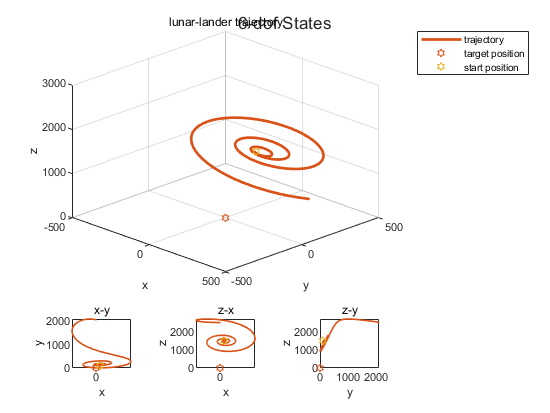

% Trajectory plot
figure('Color','White')
tiledlayout(4,3)
nexttile([3 3])
plot3(save_state(:,1),save_state(:,2),-save_state(:,3),'Color','#D95319','LineWidth',2);
title('lunar-lander trajectory')
hold on
xlabel('x'); ylabel('y'); zlabel('z');
ylim([-500 500]);
xlim([-500 500]);
view(45, 30)
grid on

plot3(state_t(1),state_t(2),-state_t(3),'h');
plot3(initial_state(1),initial_state(2),-initial_state(3),'h');
legend('trajectory','target position','start position')
hold off

nexttile;
plot(save_state(:,1),save_state(:,2),'Color','#D95319','LineWidth',1.2); hold on;
title('x-y')
xlabel('x'); ylabel('y');
plot(state_t(1),state_t(2),'h');
plot(initial_state(1),initial_state(2),'h');
hold off

nexttile;
plot(save_state(:,1),-save_state(:,3),'Color','#D95319','LineWidth',1.2); hold on
title('z-x')
xlabel('x'); ylabel('z');
plot(state_t(1),-state_t(3),'h');
plot(initial_state(1),-initial_state(3),'h');
hold off

nexttile;
plot(save_state(:,2),-save_state(:,3),'Color','#D95319','LineWidth',1.2); hold on
title('z-y')
xlabel('y'); ylabel('z');
plot(state_t(2),-state_t(3),'h');
plot(initial_state(2),-initial_state(3),'h');
hold off

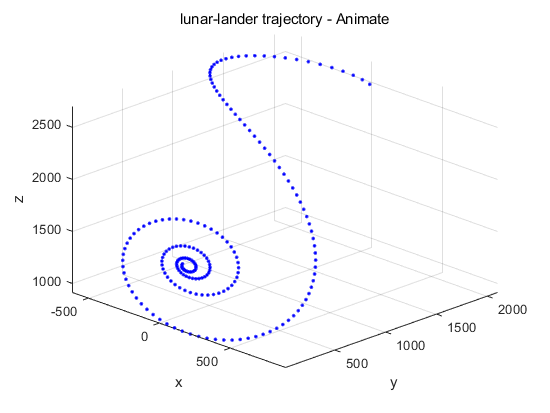

% Trajectory animation plot
x_min = min(save_state(:,1));
x_max = max(save_state(:,1));
y_min = min(save_state(:,2));
y_max = max(save_state(:,2));
z_min = min(-save_state(:,3));
z_max = max(-save_state(:,3));
figure('Color','White')
pause(1)
hold on
for i = 1 : length(save_state(:,1))
    ax = gcf;
    plot3(save_state(i,1),save_state(i,2),-save_state(i,3),'.b');
    xlabel('x'); ylabel('y'); zlabel('z');
    grid on
    pause(0.1)
    view(45, 30)
    xlim([x_min x_max])
    ylim([y_min y_max])
    zlim([z_min z_max])
end
title('lunar-lander trajectory - Animate')
hold off

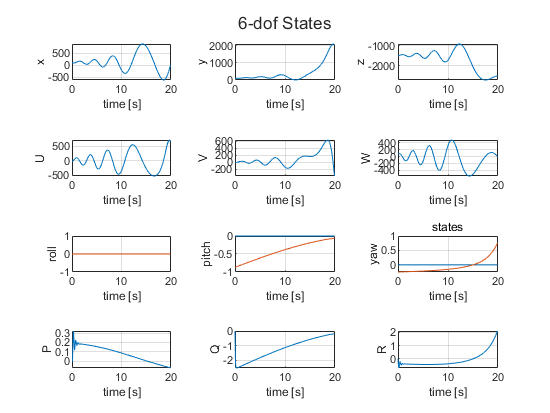


% 6-dof states
figure('Color','White')
states_plot = tiledlayout(4,3);
title(states_plot,'6-dof States')
tf = length(save_state(:,1)) * dt;
for i = 1 : 6
    nexttile;
    plot(0:dt:tf-dt, save_state(:,i));
    xlabel('time [s]')
    id = state_id(i);
    ylabel(id)
    grid on
end

for i = 7 : 9
    nexttile;
    plot(0:dt:tf-dt, save_state(:,i),0:dt:tf-dt, angle_cmd(:,i-6));
    xlabel('time [s]')
    id = state_id(i);
    ylabel(id)
%     legend('6DOF','cmd')
    grid on
end
title('states')

for i = 10 : 12
    nexttile
    plot(0:dt:tf-dt, save_state(:,i));
    xlabel('time [s]')
    id = state_id(i);
    ylabel(id)
    grid on
end